# HAMR-6 SE(2) locomotion study

## 3D reconstruction of trajectory and kinematics

The goal of this section is to take the properties of HAMR reconstruct it in 3D and add the trajectory of the robot to it. Here's a marked up top view of HAMR-6 and that will be the subject of 3D reconstruction study. **All units are in mm.**

### Respecting form-factor symmetry

In this subsection, we shall use our bounding box measurements and respect the symmetry of the design. This would mean, as shown in the top-view, the bounding boxes shall have equal opposing sides.

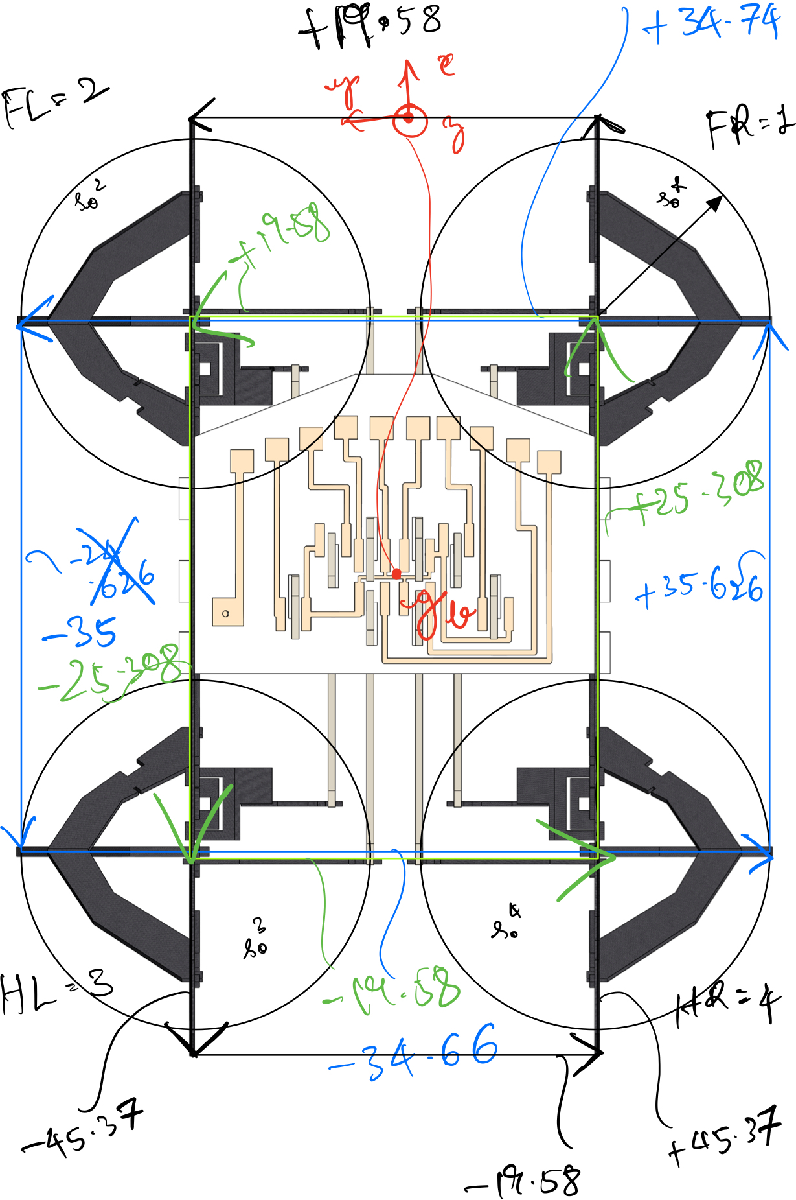

There and 3 bounding boxes above-- the green one connects the bases of each spherical five-bar transmission (SFB), the blue one connects the feet-tips, and the black one connects the tips of the body excluding the legs. These boxes are at different levels, and hence we need to handle that to get the right 3D reconstruction. Hence, these bounding boxes are defined as a set of cyclic vectors forming a closed shape (boxes in the quadrupedal case)-- the vectors are defined in a global rest frame that is aligned with the body frame before the motion begins. Assume the initial point of the first vector (tail) to be the origin for this set of vectors. We shall exploit the fact that all the these bounding boxes are centered around the body frame of the robot. NOTE: THE BOXES ARE AT DIFFERENT Z-LEVELS. This must be accounted for when doing the transformations.

Let's first round off all quantities to 3 significant digits instead of 4 significant digit measurement.

% add utilities function toe the path
addpath 'Data'\ 'Utility Functions'\;

% foot bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
foot_bound = [[0, 34.74, 0]; [-35, 0, 0]; [0, -34.66, 0]; [35.626, 0, 0]]

foot_bound =          0   34.7400         0
  -35.0000         0         0
         0  -34.6600         0
   35.6260         0         0


foot_bound = boundboxmean(foot_bound, true) % true because it is designed to be a square

foot_bound =      0    35     0
   -35     0     0
     0   -35     0
    35     0     0


% hip bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
hip_bound = [[0, 19.58, 0]; [-25.308, 0, 0]; [0, -19.58, 0]; [25.308, 0, 0]]

hip_bound =          0   19.5800         0
  -25.3080         0         0
         0  -19.5800         0
   25.3080         0         0


hip_bound = boundboxmean(hip_bound, false)

hip_bound =          0   19.6000         0
  -25.3000         0         0
         0  -19.6000         0
   25.3000         0         0


% body w/o leg bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% there's a top and a bottom version for this bounding box and this will be addressed in the next section.
bodywoleg_bound = [[0, 19.58, 0]; [-45.37, 0, 0]; [0, -19.58, 0]; [45.37, 0, 0]]

bodywoleg_bound =          0   19.5800         0
  -45.3700         0         0
         0  -19.5800         0
   45.3700         0         0


bodywoleg_bound = boundboxmean(bodywoleg_bound, false)

bodywoleg_bound =          0   19.6000         0
  -45.4000         0         0
         0  -19.6000         0
   45.4000         0         0


### Translational transformations to body center

Now, let's compute the transforms from the body frame to the frames of interest-- we shall break down transformations into translations and rotations. Here's an isometric view of the 3D reconstruction of the robot we need and also the z change between various bounding boxes.

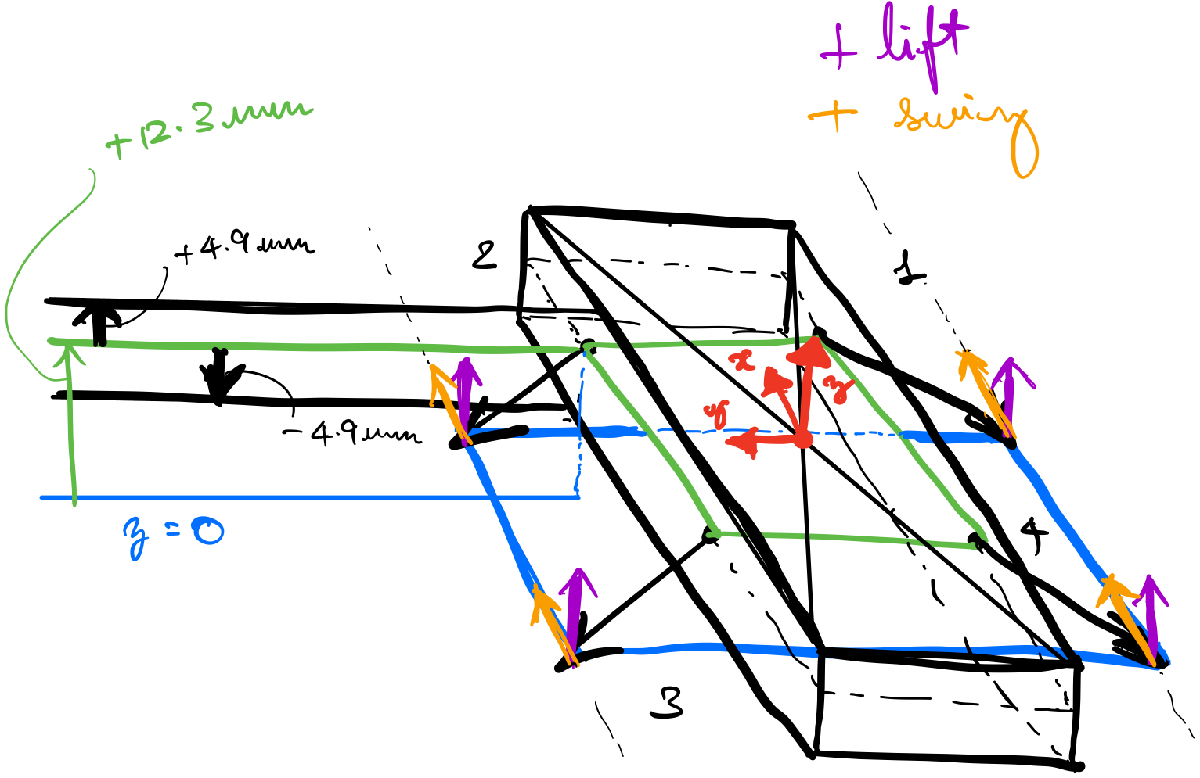

% z-change in HAMR6 with markers on (body center in the middle of the top plate in 2017 Ben Goldberg's: 10.1109/IROS.2017.8206249)
z_body2hipbox = [0, 0, -4.19];
z_body2bodyboundboxT = [0, 0, 0]; % top body bound box is at the body frame level
z_body2bodyboundboxB = [0, 0, -4.19*2];

% find the location of frame 1b hip-frame from the center of the robot-- translational sub-group of SE3
%%%%%%%%%% just h denotes SE2 transformations: ht translations, hR rotations
%%%%%%%%%% h3 denotes SE3 transformations: ht3 translations, hR3 rotations
%%%%%%%%%% small 'h' stands for vector form of se3/2 transformation, 'H' stands for the group action form of se3/2 transformation
h3_b__hip = boundbox2ht3transform(hip_bound) + repmat(z_body2hipbox, [size(hip_bound, 1), 1]); % repeat over rows
h3_b__1b = h3_b__hip(1, :);
h3_b__2b = h3_b__hip(2, :);
h3_b__3b = h3_b__hip(3, :);
h3_b__4b = h3_b__hip(4, :);

% find the location of the top and bottom bounding boxes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TOP
h3_b__bboundT = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxT, [size(bodywoleg_bound, 1), 1]);
h3_b__1cT = h3_b__bboundT(1, :);
h3_b__2cT = h3_b__bboundT(2, :);
h3_b__3cT = h3_b__bboundT(3, :);
h3_b__4cT = h3_b__bboundT(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BOT
h3_b__bboundB = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxB, [size(bodywoleg_bound, 1), 1]);
h3_b__1cB = h3_b__bboundB(1, :);
h3_b__2cB = h3_b__bboundB(2, :);
h3_b__3cB = h3_b__bboundB(3, :);
h3_b__4cB = h3_b__bboundB(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% JOIN (add links to join the top and bottom sides)
h3_b__bboundB2T = h3_b__bboundT - h3_b__bboundB;

% Finally, let's find the transformations to these frames (no rotations since they all have the same orientation as the body frame)
% SE3 transformations for the hip frame ##############################################################
H3_b__hip = t_SE3(h3_b__hip); 
H3_b__1b = H3_b__hip{1};
H3_b__2b = H3_b__hip{2};
H3_b__3b = H3_b__hip{3};
H3_b__4b = H3_b__hip{4};
% SE3 transformations for the top bounding box #######################################################
H3_b__bboundT = t_SE3(h3_b__bboundT); 
H3_b__1cT = H3_b__bboundT{1};
H3_b__2cT = H3_b__bboundT{2};
H3_b__3cT = H3_b__bboundT{3};
H3_b__4cT = H3_b__bboundT{4};
% SE3 transformations for the bot bounding box #######################################################
H3_b__bboundB = t_SE3(h3_b__bboundB);
H3_b__1cB = H3_b__bboundB{1};
H3_b__2cB = H3_b__bboundB{2};
H3_b__3cB = H3_b__bboundB{3};
H3_b__4cB = H3_b__bboundB{4};
% compile the transforms
H3_b__ib = H3_b__hip;
H3_b__icT = H3_b__bboundT;
H3_b__icB = H3_b__bboundB;

Let's plot what we have so far and visualize it from a few different view points.

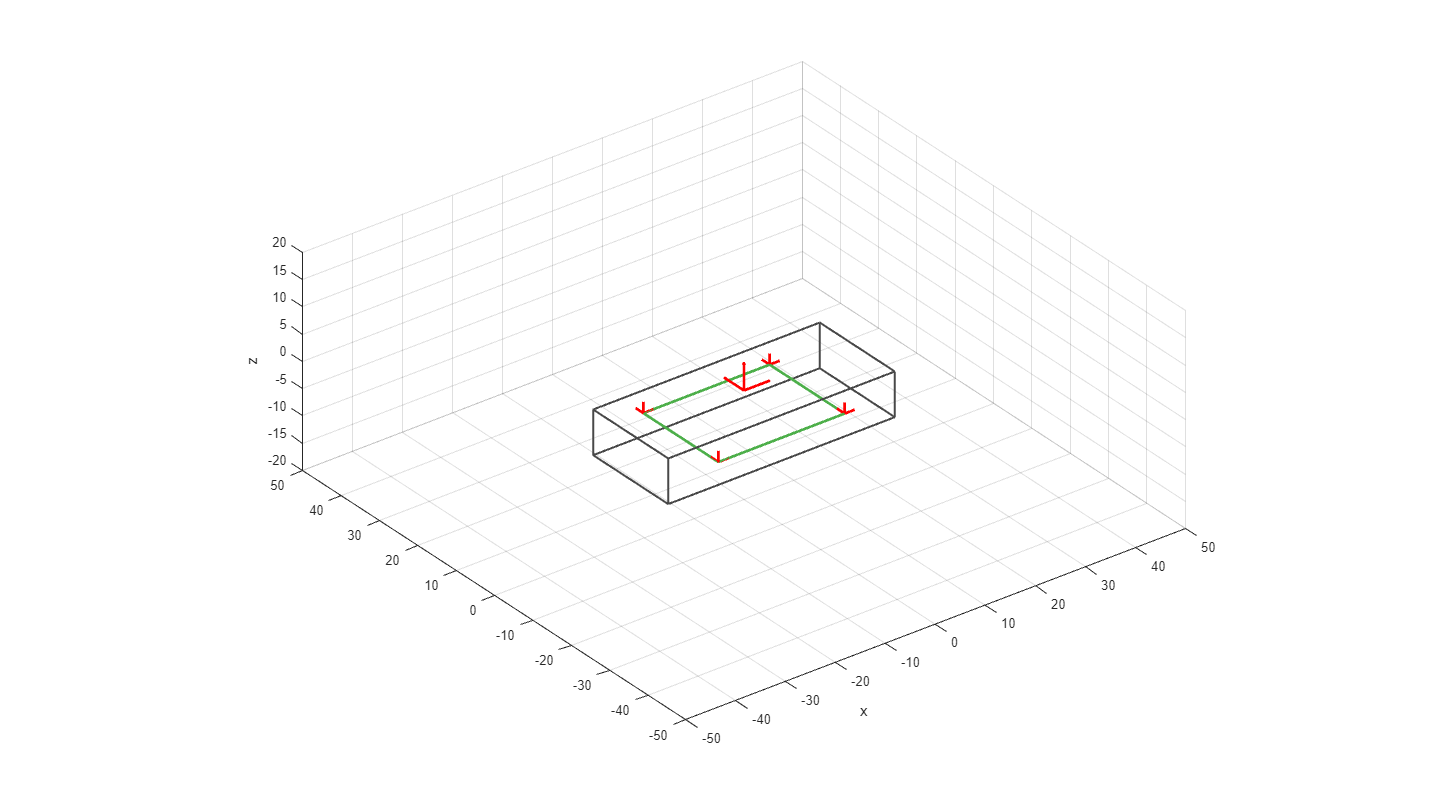

figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% plot the hip bound box %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(h3_b__hip(:, 1), h3_b__hip(:, 2), h3_b__hip(:, 3), hip_bound(:, 1), hip_bound(:, 2), hip_bound(:, 3),...
    'LineWidth', 2, 'Color', [77, 175, 74]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off');
% set some props %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hold on; view(-37.5, 30); axis square equal; axis([-50 50 -50 50 -20 20]); xlabel('x'); zlabel('y'); zlabel('z');
% plot the body bound boxes and complete it %%%%%%%%%%%%%%%%%%%
quiver3(h3_b__bboundT(:, 1), h3_b__bboundT(:, 2), h3_b__bboundT(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % top box
quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % bottom box
quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), h3_b__bboundB2T(:, 1), h3_b__bboundB2T(:, 2), h3_b__bboundB2T(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % connection
% plot the body frame %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(zeros(3,1), zeros(3,1), zeros(3,1), [5, 0, 0]', [0, 5, 0]', [0, 0, 5]', 'LineWidth', 2, 'Color', 'r', 'AutoScale', 'off');
% plot the hip frames %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:size(h3_b__hip, 1)
    quiver3(h3_b__hip(i,1)*ones(3,1), h3_b__hip(i,2)*ones(3,1), h3_b__hip(i,3)*ones(3,1), [2, 0, 0]', [0, 2, 0]', [0, 0, 2]',...
    'LineWidth', 2, 'Color', 'r', 'AutoScale', 'off');
end

### Full SE(3) transformations in body frame

Let's model the legs about the SFB using lift and swing angles inputs-- the positive lift and swing angles are shown in the 3D reconstruction sketch.

Thus, the leg transformations from the SFB are characterized by a rotation along Z for a swing angle ($-\alpha$ for the left side of the body and $\alpha$  for he right side of the body) followed by a rotation along Y for a lift angle ($\beta$ for the left side of the body and $-\beta$  for he right side of the body)-- let's call this frame 1bR (for rotated 1b frame).

syms alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4 real
h3_ib__ibR_z = [alpha_1, -alpha_2, -alpha_3, alpha_4]'; h3_ib__ibR_y = [-beta_1, beta_2, beta_3, -beta_4]';
H3_ib__ibR_z = rotz_SE3(h3_ib__ibR_z); H3_ib__ibR_y = roty_SE3(h3_ib__ibR_y);
H3_1b__1bR = simplify(H3_ib__ibR_z{1}*H3_ib__ibR_y{1});
H3_2b__2bR = simplify(H3_ib__ibR_z{2}*H3_ib__ibR_y{2});
H3_3b__3bR = simplify(H3_ib__ibR_z{3}*H3_ib__ibR_y{3});
H3_4b__4bR = simplify(H3_ib__ibR_z{4}*H3_ib__ibR_y{4});

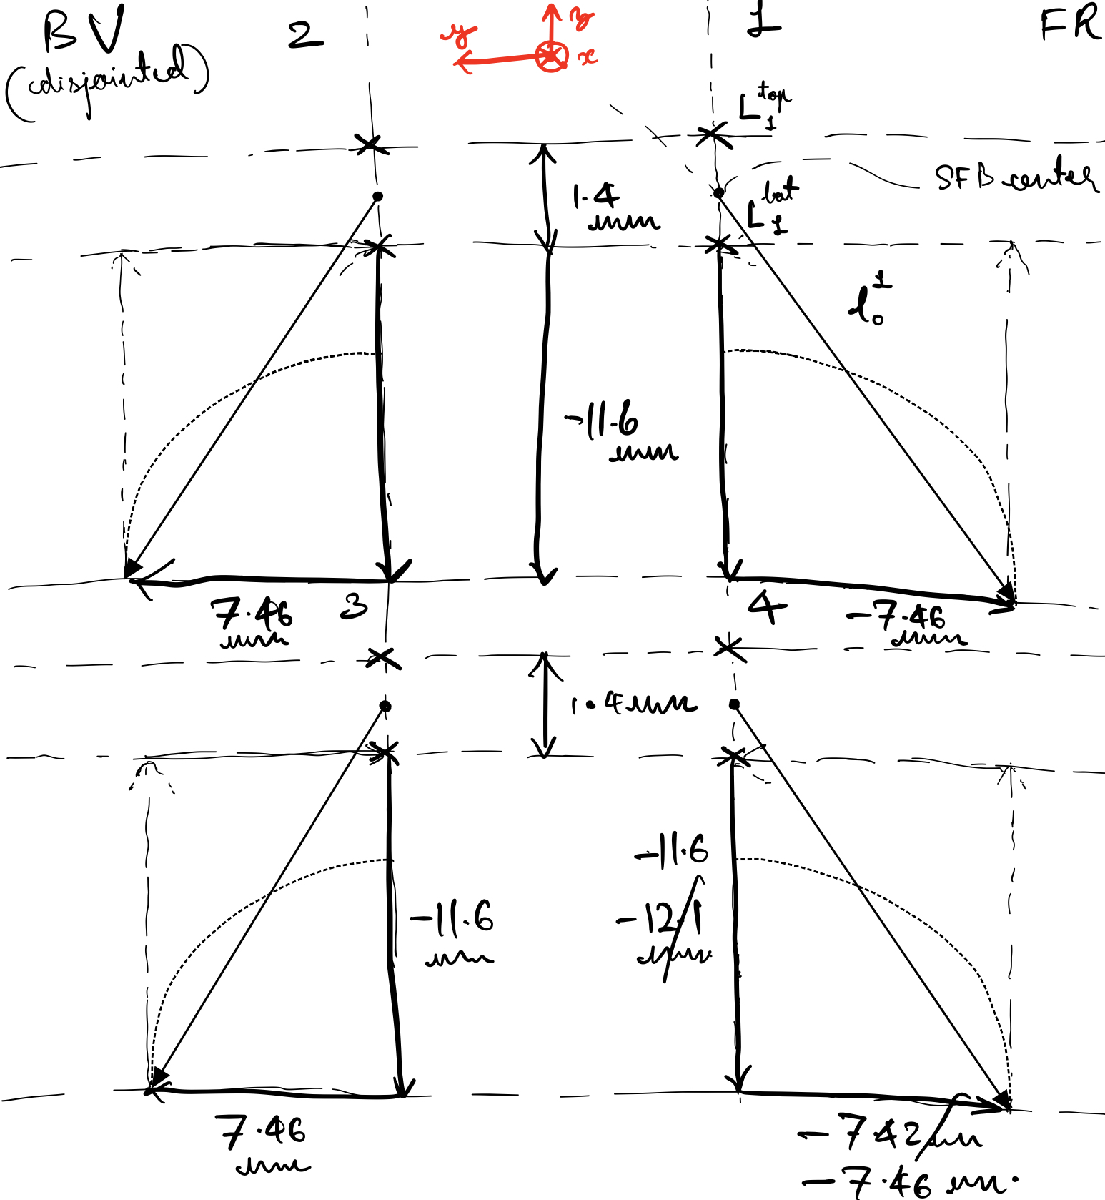

Then, we translate along the directions specified in the figure above-- this will give us the foot-tip frames.

h3_1bR__1 = [0, -7.46, -11.6];
h3_2bR__2 = [0, +7.46, -11.6];
h3_3bR__3 = [0, +7.46, -11.6];
h3_4bR__4 = [0, -7.46, -11.6];
H3_1bR__1 = t_SE3(h3_1bR__1);
H3_2bR__2 = t_SE3(h3_2bR__2);
H3_3bR__3 = t_SE3(h3_3bR__3);
H3_4bR__4 = t_SE3(h3_4bR__4);
% Compute the complete transformation from hip-frame to the foot
H3_1b__1 = simplify(H3_1b__1bR*H3_1bR__1)

$$H3\_1b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & -\sin\left(\alpha_{1}\right) & -\cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{373\,\sin\left(\alpha_{1}\right)}{50}+\frac{58\,\cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)}{5}\\ \cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{58\,\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)}{5}-\frac{373\,\cos\left(\alpha_{1}\right)}{50}\\ \sin\left(\beta_{1}\right) & 0 & \cos\left(\beta_{1}\right) & -\frac{58\,\cos\left(\beta_{1}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_2b__2 = simplify(H3_2b__2bR*H3_2bR__2)

$$H3\_2b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{373\,\sin\left(\alpha_{2}\right)}{50}-\frac{58\,\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)}{5}\\ -\cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{373\,\cos\left(\alpha_{2}\right)}{50}+\frac{58\,\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)}{5}\\ -\sin\left(\beta_{2}\right) & 0 & \cos\left(\beta_{2}\right) & -\frac{58\,\cos\left(\beta_{2}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_3b__3 = simplify(H3_3b__3bR*H3_3bR__3)

$$H3\_3b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & \sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{373\,\sin\left(\alpha_{3}\right)}{50}-\frac{58\,\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)}{5}\\ -\cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{373\,\cos\left(\alpha_{3}\right)}{50}+\frac{58\,\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)}{5}\\ -\sin\left(\beta_{3}\right) & 0 & \cos\left(\beta_{3}\right) & -\frac{58\,\cos\left(\beta_{3}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_4b__4 = simplify(H3_4b__4bR*H3_4bR__4)

$$H3\_4b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & -\sin\left(\alpha_{4}\right) & -\cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{373\,\sin\left(\alpha_{4}\right)}{50}+\frac{58\,\cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)}{5}\\ \cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{58\,\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)}{5}-\frac{373\,\cos\left(\alpha_{4}\right)}{50}\\ \sin\left(\beta_{4}\right) & 0 & \cos\left(\beta_{4}\right) & -\frac{58\,\cos\left(\beta_{4}\right)}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Let's compute the transforms from the body as well
H3_b__1 = simplify(H3_b__1b*H3_1b__1)

$$H3\_b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right)\,\cos\left(\beta_{1}\right) & -\sin\left(\alpha_{1}\right) & -\cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{373\,\sin\left(\alpha_{1}\right)}{50}+\frac{58\,\cos\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)}{5}+\frac{253}{20}\\ \cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & -\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right) & \frac{58\,\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)}{5}-\frac{373\,\cos\left(\alpha_{1}\right)}{50}-\frac{49}{5}\\ \sin\left(\beta_{1}\right) & 0 & \cos\left(\beta_{1}\right) & -\frac{58\,\cos\left(\beta_{1}\right)}{5}-\frac{419}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__2 = simplify(H3_b__2b*H3_2b__2)

$$H3\_b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha_{2}\right)\,\cos\left(\beta_{2}\right) & \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{373\,\sin\left(\alpha_{2}\right)}{50}-\frac{58\,\cos\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)}{5}+\frac{253}{20}\\ -\cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right) & \frac{373\,\cos\left(\alpha_{2}\right)}{50}+\frac{58\,\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)}{5}+\frac{49}{5}\\ -\sin\left(\beta_{2}\right) & 0 & \cos\left(\beta_{2}\right) & -\frac{58\,\cos\left(\beta_{2}\right)}{5}-\frac{419}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__3 = simplify(H3_b__3b*H3_3b__3)

$$H3\_b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha_{3}\right)\,\cos\left(\beta_{3}\right) & \sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{373\,\sin\left(\alpha_{3}\right)}{50}-\frac{58\,\cos\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)}{5}-\frac{253}{20}\\ -\cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right) & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right) & \frac{373\,\cos\left(\alpha_{3}\right)}{50}+\frac{58\,\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)}{5}+\frac{49}{5}\\ -\sin\left(\beta_{3}\right) & 0 & \cos\left(\beta_{3}\right) & -\frac{58\,\cos\left(\beta_{3}\right)}{5}-\frac{419}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__4 = simplify(H3_b__4b*H3_4b__4)

$$H3\_b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha_{4}\right)\,\cos\left(\beta_{4}\right) & -\sin\left(\alpha_{4}\right) & -\cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{373\,\sin\left(\alpha_{4}\right)}{50}+\frac{58\,\cos\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)}{5}-\frac{253}{20}\\ \cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & -\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right) & \frac{58\,\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)}{5}-\frac{373\,\cos\left(\alpha_{4}\right)}{50}-\frac{49}{5}\\ \sin\left(\beta_{4}\right) & 0 & \cos\left(\beta_{4}\right) & -\frac{58\,\cos\left(\beta_{4}\right)}{5}-\frac{419}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_ib__ibR = {H3_1b__1bR, H3_2b__2bR, H3_3b__3bR, H3_4b__4bR};
H3_ibR__i = {H3_1bR__1, H3_2bR__2, H3_3bR__3, H3_4bR__4};
H3_ib__i = {H3_1b__1, H3_2b__2, H3_3b__3, H3_4b__4};
H3_b__i = {H3_b__1, H3_b__2, H3_b__3, H3_b__4};

% Let's compute the full-jacobian for each leg using the adjoint inverse operation
% -----------------------------------------------------------------------------------------------------------------------------
% Jacobians to the leg from the body -- MAP IN TWIST COORDINATES
% -----------------------------------------------------------------------------------------------------------------------------
J3_b__1 = adj_adjinv_SE3(H3_b__1, -1)

J3_b__2 = adj_adjinv_SE3(H3_b__2, -1)

J3_b__3 = adj_adjinv_SE3(H3_b__3, -1)

J3_b__4 = adj_adjinv_SE3(H3_b__4, -1)

% compile
J3_b__i = {J3_b__1, J3_b__2, J3_b__3, J3_b__4};

% -----------------------------------------------------------------------------------------------------------------------------
% Jacobians to the leg frame from the corresponding hip frame 
% -----------------------------------------------------------------------------------------------------------------------------
% +ve swing velocity is measured about the (-Z)-axis for the left side of the body and (+Z)-axis for the right side of the body
% +ve lift velocity is measured about the (+Y)-axis for the left side of the body and (-Y)-axis for the right side of the body
alpha_circ_1 = [0, 0, 1, 0, 0, 0]'; alpha_circ_2 = [0, 0, -1, 0, 0, 0]'; alpha_circ_3 = [0, 0, -1, 0, 0, 0]'; alpha_circ_4 = [0, 0, 1, 0, 0, 0]';
beta_circ_1 = [0, -1, 0, 0, 0, 0]'; beta_circ_2 = [0, 1, 0, 0, 0, 0]'; beta_circ_3 = [0, 1, 0, 0, 0, 0]'; beta_circ_4 = [0, -1, 0, 0, 0, 0]';
circ_1 = [alpha_circ_1, beta_circ_1]; circ_2 = [alpha_circ_2, beta_circ_2]; circ_3 = [alpha_circ_3, beta_circ_3]; circ_4 = [alpha_circ_4, beta_circ_4];

% Get the jacobians from the hip frame -- first set of columns correspond to swing velocities, alpha_dot and the second set of columns correspond to lift
% velocites, beta_dot
J3_1b__1 = adj_adjinv_SE3(H3_1b__1, -1)*circ_1

$$J3\_1b\_\_1 = \left(\begin{array}{cc} \sin\left(\beta_{1}\right) & -\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right)\\ 0 & -\cos\left(\alpha_{1}\right)\\ \cos\left(\beta_{1}\right) & \sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)\\ \frac{373\,\cos\left(\beta_{1}\right)}{50} & \frac{58\,\cos\left(\alpha_{1}\right)}{5}+\frac{373\,\sin\left(\alpha_{1}\right)\,\sin\left(\beta_{1}\right)}{50}\\ \frac{58\,\sin\left(\beta_{1}\right)}{5} & -\frac{58\,\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right)}{5}\\ -\frac{373\,\sin\left(\beta_{1}\right)}{50} & \frac{373\,\cos\left(\beta_{1}\right)\,\sin\left(\alpha_{1}\right)}{50} \end{array}\right)$$

J3_2b__2 = adj_adjinv_SE3(H3_2b__2, -1)*circ_2

$$J3\_2b\_\_2 = \left(\begin{array}{cc} \sin\left(\beta_{2}\right) & -\cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right)\\ 0 & \cos\left(\alpha_{2}\right)\\ -\cos\left(\beta_{2}\right) & -\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)\\ \frac{373\,\cos\left(\beta_{2}\right)}{50} & \frac{373\,\sin\left(\alpha_{2}\right)\,\sin\left(\beta_{2}\right)}{50}-\frac{58\,\cos\left(\alpha_{2}\right)}{5}\\ \frac{58\,\sin\left(\beta_{2}\right)}{5} & -\frac{58\,\cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right)}{5}\\ \frac{373\,\sin\left(\beta_{2}\right)}{50} & -\frac{373\,\cos\left(\beta_{2}\right)\,\sin\left(\alpha_{2}\right)}{50} \end{array}\right)$$

J3_3b__3 = adj_adjinv_SE3(H3_3b__3, -1)*circ_3

$$J3\_3b\_\_3 = \left(\begin{array}{cc} \sin\left(\beta_{3}\right) & -\cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right)\\ 0 & \cos\left(\alpha_{3}\right)\\ -\cos\left(\beta_{3}\right) & -\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)\\ \frac{373\,\cos\left(\beta_{3}\right)}{50} & \frac{373\,\sin\left(\alpha_{3}\right)\,\sin\left(\beta_{3}\right)}{50}-\frac{58\,\cos\left(\alpha_{3}\right)}{5}\\ \frac{58\,\sin\left(\beta_{3}\right)}{5} & -\frac{58\,\cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right)}{5}\\ \frac{373\,\sin\left(\beta_{3}\right)}{50} & -\frac{373\,\cos\left(\beta_{3}\right)\,\sin\left(\alpha_{3}\right)}{50} \end{array}\right)$$

J3_4b__4 = adj_adjinv_SE3(H3_4b__4, -1)*circ_4

$$J3\_4b\_\_4 = \left(\begin{array}{cc} \sin\left(\beta_{4}\right) & -\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right)\\ 0 & -\cos\left(\alpha_{4}\right)\\ \cos\left(\beta_{4}\right) & \sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)\\ \frac{373\,\cos\left(\beta_{4}\right)}{50} & \frac{58\,\cos\left(\alpha_{4}\right)}{5}+\frac{373\,\sin\left(\alpha_{4}\right)\,\sin\left(\beta_{4}\right)}{50}\\ \frac{58\,\sin\left(\beta_{4}\right)}{5} & -\frac{58\,\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right)}{5}\\ -\frac{373\,\sin\left(\beta_{4}\right)}{50} & \frac{373\,\cos\left(\beta_{4}\right)\,\sin\left(\alpha_{4}\right)}{50} \end{array}\right)$$

% compile
J3_ib__i = {J3_1b__1, J3_2b__2, J3_3b__3, J3_4b__4};

% -----------------------------------------------------------------------------------------------------------------------------
% FULL Jacobian to the leg frame from
% -----------------------------------------------------------------------------------------------------------------------------
J3_full = computefulljacobianSE3( {J3_b__1, J3_b__2, J3_b__3, J3_b__4}, {J3_1b__1, J3_2b__2, J3_3b__3, J3_4b__4}, {1, 2, 3, 4} );

% Convert these to functions and store it in a struct for later access
fH3_b__1 = matlabFunction(H3_b__1, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fH3_b__2 = matlabFunction(H3_b__2, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fH3_b__3 = matlabFunction(H3_b__3, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fH3_b__4 = matlabFunction(H3_b__4, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fH3_b__i = {fH3_b__1, fH3_b__2, fH3_b__3, fH3_b__4};

fJ3_b__1 = matlabFunction(J3_b__1, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_b__2 = matlabFunction(J3_b__2, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_b__3 = matlabFunction(J3_b__3, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_b__4 = matlabFunction(J3_b__4, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_b__i = {fJ3_b__1, fJ3_b__2, fJ3_b__3, fJ3_b__4};

fJ3_1b__1 = matlabFunction(J3_1b__1, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_2b__2 = matlabFunction(J3_2b__2, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_3b__3 = matlabFunction(J3_3b__3, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_4b__4 = matlabFunction(J3_4b__4, 'Vars', [alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4]);
fJ3_ib__i = {fJ3_1b__1, fJ3_2b__2, fJ3_3b__3, fJ3_4b__4};

% Initialize the struct and start storing computed quantities
HAMR_6_SE3 = [];
HAMR_6_SE3.transforms = [];
HAMR_6_SE3.transforms.num = [];
HAMR_6_SE3.transforms.sym = [];
HAMR_6_SE3.transforms.fun = [];
% numeric transforms
HAMR_6_SE3.transforms.num.H3_b__ib = H3_b__ib; % hip transforms
HAMR_6_SE3.transforms.num.H3_b__icT = H3_b__icT; % bounding top transforms
HAMR_6_SE3.transforms.num.H3_b__icB = H3_b__icB; % bounding bot transforms
% symbolic transforms
HAMR_6_SE3.transforms.sym.H3_ib__ibR = H3_ib__ibR; % hip to swing-lift rotated hip
HAMR_6_SE3.transforms.sym.H3_ibR__i = H3_ibR__i; % swing-lift rotated hip to foot
HAMR_6_SE3.transforms.sym.H3_ib__i = H3_ib__i; % hip to foot
HAMR_6_SE3.transforms.sym.H3_b__i = H3_b__i; % body to foot
% functional transforms
HAMR_6_SE3.transforms.fun.fH3_b__i = fH3_b__i; % body to foot transform functions
HAMR_6_SE3.transforms.fun.fJ3_b__i = fJ3_b__i; % body to foot jacobian functions
HAMR_6_SE3.transforms.fun.fJ3_ib__i = fJ3_ib__i; % hip to foot transform functions

% Store the data
save('Data\HAMR6_SE3_kinematics.mat');